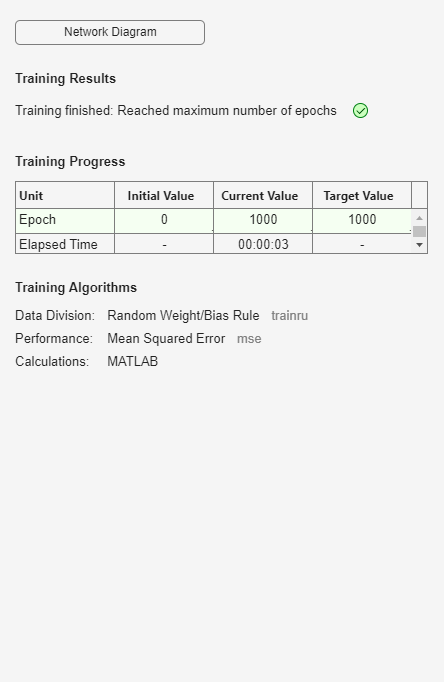

%福冈与中国六城市的相似性比较（变量除以标准差）
clear                                       %清理内存
P=[14.1865 14.7286 15.5418 16.9876 16.1744 14.7286 
2.8297 3.6757 4.1483 5.4669 4.9534 2.8472 
6.9131 6.5251 5.4016 5.3484 5.7834 3.8775 
-3.1628 -2.6561 -1.4586 -0.7523 -0.6909 -0.7062 
0.8319 1.2260 2.0142 3.5029 3.2840 2.4521]; %训练样本的输入变量
net=newc([-1 1;-1 1;-1 1;-1 1;-1 1],3);     %创建五变量二分类的竞争型网络
net.trainParam.epochs=1000;                 %指定最大训练次数
net=train(net,P);                           %训练网络

Y=sim(net,P);                               %数值仿真结果
Yc=vec2ind(Y)                               %给出分类向量

Yc =      3     3     1     2     2     1


Q=[14.6383 4.3525 6.2591 -1.2590 2.7148]';  %输入福冈的信号
y_test=sim(net,Q);                          %福冈数值仿真
yc_test=vec2ind(y_test)                     %福冈归类结果

yc_test = 1